## 0. Initialize Parameters

L = 1200; % Length of bridge
n = 1200; % Discretize into 1 mm seg.
P = 400; % Total weight of train [N]
x = linspace(0, L, n+1); % x-axis

## 1. SFD, BMD under train loading

x_train = [52 228 392 568 732 908]; % Train Load Locations
P_train = [1 1 1 1 1 1] * P/6;
n_train = 10; % num of train locations
SFDi = zeros(n_train, n+1); % 1 SFD for each train loc.
BMDi = zeros(n_train, n+1); % 1 BMD for each train loc.
% Solve for SFD and BMD with the train at different locations

for i = 1:n_train
    % start location of train
    train_pos = x_train - (n_train - i) * L / n_train

    % sum of moments at A eqn
    real_train_pos = train_pos(train_pos >= 0 & train_pos <= L)
    real_P = P_train(train_pos >= 0 & train_pos <= L)
    moment_A = sum(real_train_pos.*real_P)

    % sum of Fy eqn
    By = moment_A / L
    Ay = sum(real_P) - By

    % construct applied loads
    % w(x)
    SFDi(i, 1) = Ay;
    next_ind = 1;
    for xi = 2:n
        SFDi(i, xi) = SFDi(i, xi-1);
        if next_ind <= length(real_P) & xi >= real_train_pos(next_ind)
            SFDi(i, xi) = SFDi(i, xi) - real_P(next_ind);
            next_ind = next_ind + 1;
        end
    end
    SFDi(i, end) = SFDi(i, end-1) + By;
    BMDi(i,:) = cumsum(SFDi(i,:).*(L/n));
    % plot(x, SFDi)
    % plot(x, BMDi)
end

train_pos =        -1028        -852        -688        -512        -348        -172



real_train_pos =

  1×0 empty double row vector




real_P =

  1×0 empty double row vector



moment_A = 0

By = 0

Ay = 0

train_pos =   -908  -732  -568  -392  -228   -52



real_train_pos =

  1×0 empty double row vector




real_P =

  1×0 empty double row vector



moment_A = 0

By = 0

Ay = 0

train_pos =   -788  -612  -448  -272  -108    68


real_train_pos = 68

real_P = 66.6667

moment_A = 4.5333e+03

By = 3.7778

Ay = 62.8889

train_pos =   -668  -492  -328  -152    12   188


real_train_pos =     12   188


real_P =    66.6667   66.6667


moment_A = 1.3333e+04

By = 11.1111

Ay = 122.2222

train_pos =   -548  -372  -208   -32   132   308


real_train_pos =    132   308


real_P =    66.6667   66.6667


moment_A = 2.9333e+04

By = 24.4444

Ay = 108.8889

train_pos =   -428  -252   -88    88   252   428


real_train_pos =     88   252   428


real_P =    66.6667   66.6667   66.6667


moment_A = 51200

By = 42.6667

Ay = 157.3333

train_pos =   -308  -132    32   208   372   548


real_train_pos =     32   208   372   548


real_P =    66.6667   66.6667   66.6667   66.6667


moment_A = 7.7333e+04

By = 64.4444

Ay = 202.2222

train_pos =   -188   -12   152   328   492   668


real_train_pos =    152   328   492   668


real_P =    66.6667   66.6667   66.6667   66.6667


moment_A = 1.0933e+05

By = 91.1111

Ay = 175.5556

train_pos =    -68   108   272   448   612   788


real_train_pos =    108   272   448   612   788


real_P =    66.6667   66.6667   66.6667   66.6667   66.6667


moment_A = 1.4853e+05

By = 123.7778

Ay = 209.5556

train_pos =     52   228   392   568   732   908


real_train_pos =     52   228   392   568   732   908


real_P =    66.6667   66.6667   66.6667   66.6667   66.6667   66.6667


moment_A = 1.9200e+05

By = 160.0000

Ay = 240.0000

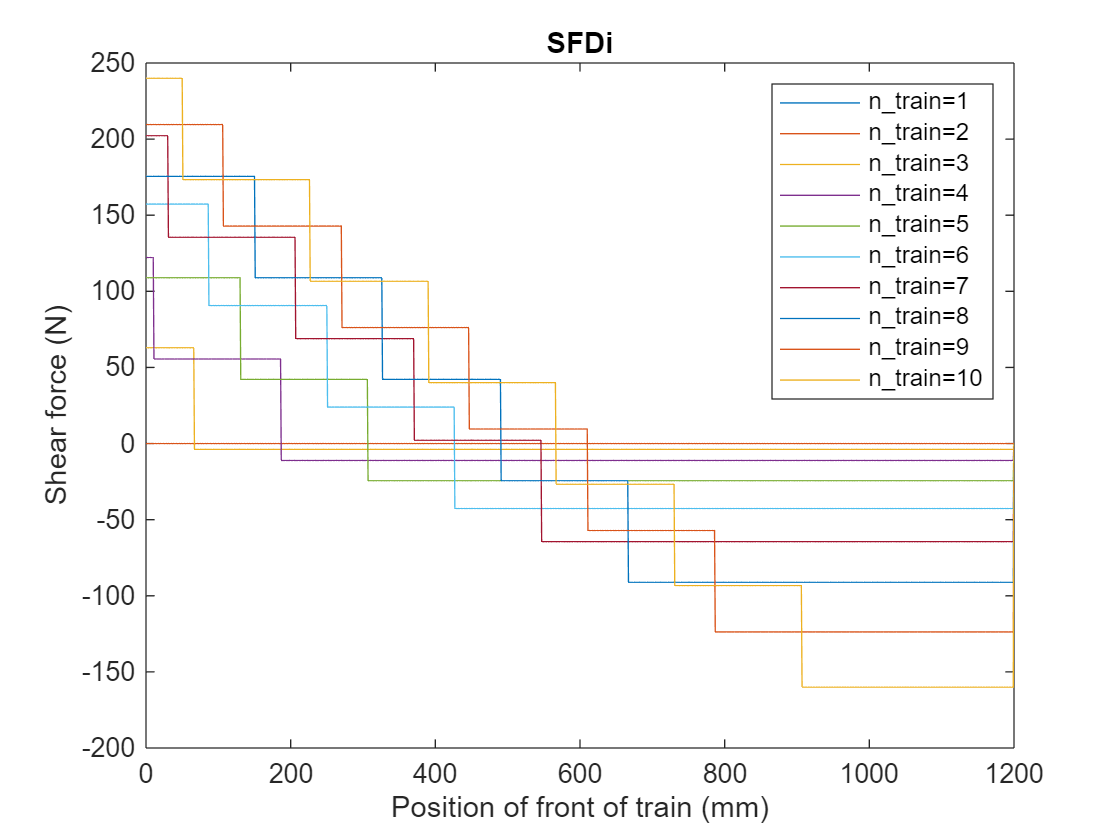


for i = 1:n_train
    plot(x, SFDi(i,:), DisplayName="n\_train="+i)
    hold on
end
legend()
title("SFDi")
xlabel("Position of front of train (mm)")
ylabel("Shear force (N)")
hold off

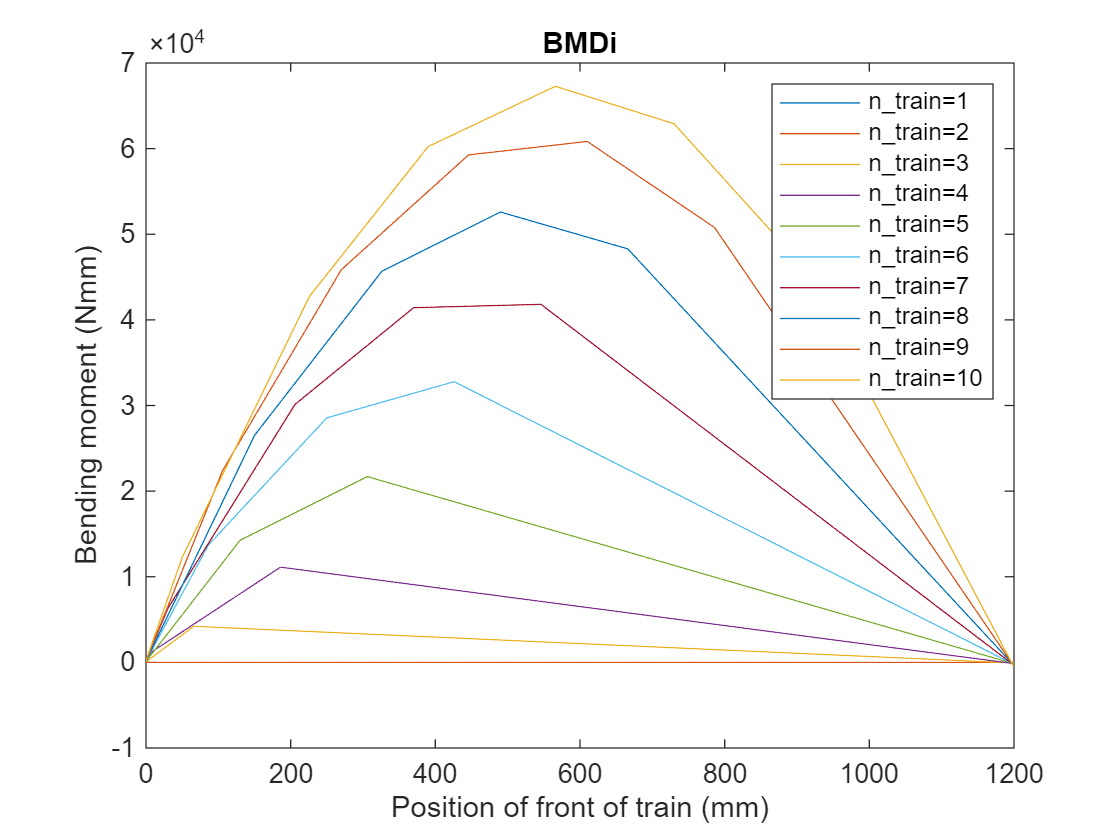


for i = 1:n_train
    plot(x, BMDi(i,:), DisplayName="n\_train="+i)
    hold on
end
legend()
title("BMDi")
xlabel("Position of front of train (mm)")
ylabel("Bending moment (Nmm)")
hold off



SFD = max(abs(SFDi)) % SFD envelope

SFD =   240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000  240.0000


BMD = max(BMDi) % BMD envelope

BMD = 1.0e+04 *

    0.0240    0.0480    0.0720    0.0960    0.1200    0.1440    0.1680    0.1920    0.2160    0.2400    0.2640    0.2880    0.3120    0.3360    0.3600    0.3840    0.4080    0.4320    0.4560    0.4800    0.5040    0.5280    0.5520    0.5760    0.6000    0.6240    0.6480    0.6720    0.6960    0.7200    0.7440    0.7680    0.7920    0.8160    0.8400    0.8640    0.8880    0.9120    0.9360    0.9600    0.9840    1.0080    1.0320    1.0560    1.0800    1.1040    1.1280    1.1520    1.1760    1.2000


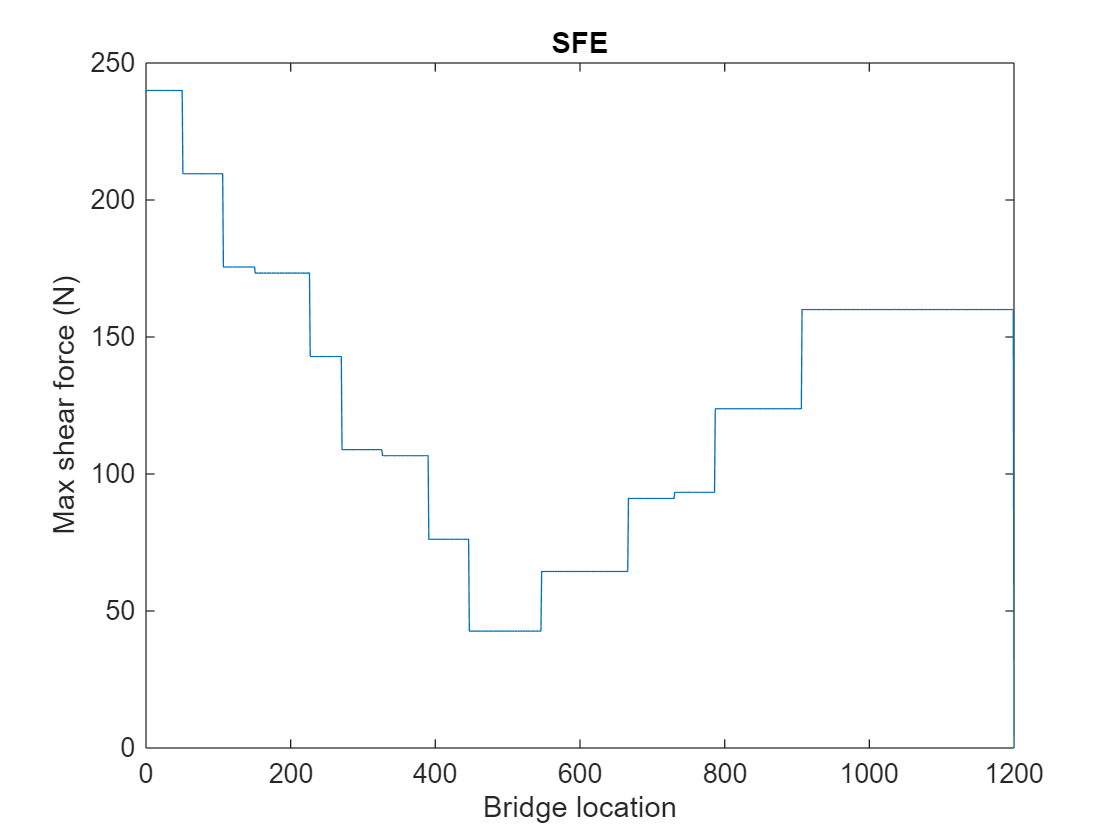


plot(x, SFD)
title("SFE")
xlabel("Bridge location")
ylabel("Max shear force (N)")

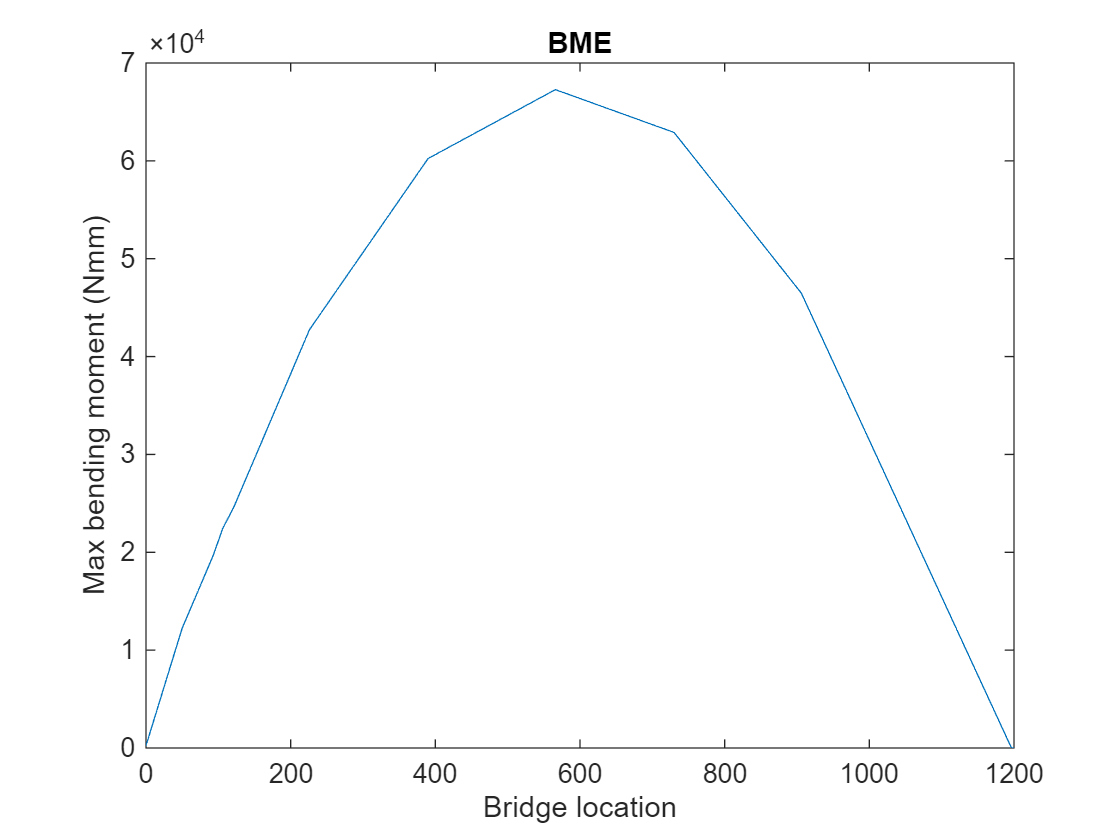


plot(x, BMD)
title("BME")
xlabel("Bridge location")
ylabel("Max bending moment (Nmm)")

## 2. Define Bridge Parameters

% = xc, bft, tft,
% param_tf = [0, 100, 1.27;
%         400, 100, 2.54;
%         800, 100, 1.27];  this is me experimenting with changing
%         cross-sections; for now we don't need this but the code is
%         written to work with changing cross-sections as well

% = x_c, b, h
param_tf = [0, 100, 1.27];
param_glue = [0, 5, 1.27];
param_side = [0, 1.27, 75];
param_bot = [0, 80-1.27*2, 1.27];

%x_c Location, x, of cross-section change
%bft Top Flange Width
%tft Top Flange Thickness

% % Extracting user input assuming linear relationship
% bft = interp1(param(:,1), param(:,2), x)
% tft = interp1(param(:,1), param(:,3), x)

btf = zeros(1, n+1);
ttf = zeros(1, n+1);
bglue = zeros(1, n+1);
hglue = zeros(1, n+1);
bside = zeros(1, n+1);
hside = zeros(1, n+1);
bbot = zeros(1, n+1);
hbot = zeros(1, n+1);

btf(1,1) = param_tf(1,2);
ttf(1,1) = param_tf(1,3);
bglue(1,1) = param_glue(1,2);
hglue(1,1) = param_glue(1,3);
bside(1,1) = param_side(1,2);
hside(1,1) = param_side(1,3);
bbot(1,1) = param_bot(1,2);
hbot(1,1) = param_bot(1,3);

next_ind_tf = 2;
next_ind_glue = 2;
next_ind_side = 2;
next_ind_bot = 2;
for i = 2 : n+1
    btf(1, i) = btf(1, i-1);
    ttf(1, i) = ttf(1, i-1);
    bglue(1, i) = bglue(1, i-1);
    hglue(1, i) = hglue(1, i-1);
    bside(1, i) = bside(1, i-1);
    hside(1, i) = hside(1, i-1);
    bbot(1, i) = bbot(1, i-1);
    hbot(1, i) = hbot(1, i-1);

    if next_ind_tf <= length(param_tf(:,1)) & i >= param_tf(next_ind_tf, 1)
        btf(1, i) = param_tf(next_ind_tf, 2);
        ttf(1, i) = param_tf(next_ind_tf, 3);
        next_ind_tf = next_ind_tf + 1;
    end
    if next_ind_glue <= length(param_glue(:,1)) & i >= param_glue(next_ind_glue, 1)
        bglue(1, i) = param_glue(next_ind_glue, 2);
        hglue(1, i) = param_glue(next_ind_glue, 3);
        next_ind_glue = next_ind_glue + 1;
    end
    if next_ind_side <= length(param_side(:,1)) & i >= param_side(next_ind_side, 1)
        bside(1, i) = param_side(next_ind_side, 2);
        hside(1, i) = param_side(next_ind_side, 3);
        next_ind_side = next_ind_side + 1;
    end
    if next_ind_bot <= length(param_bot(:,1)) & i >= param_bot(next_ind_bot, 1)
        bbot(1, i) = param_bot(next_ind_bot, 2);
        hbot(1, i) = param_bot(next_ind_bot, 3);
        next_ind_bot = next_ind_bot + 1;
    end
end

btf

btf =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100


ttf

ttf =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


bglue

bglue =      5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5


hglue

hglue =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


bside

bside =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


hside

hside =     75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75


bbot

bbot =    77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600   77.4600


hbot

hbot =     1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700    1.2700


## 3. Calculate Sectional Properties

% ybar. location of centroidal axis from the bottom

Aside = bside .* hside

Aside =    95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500   95.2500


yside = hside ./ 2

yside =    37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000   37.5000


Iside = bside .* (hside.^3) ./ 12

Iside = 1.0e+04 *

    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648    4.4648



Abot = bbot .* hbot

Abot =    98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742   98.3742


ybot = hbot ./ 2

ybot =     0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350    0.6350


Ibot = bbot .* (hbot.^3) ./ 12

Ibot =    13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223   13.2223



Atf = btf .* ttf

Atf =    127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127


ytf = hside + ttf./2

ytf =    75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350   75.6350


Itf = btf .* (ttf.^3) ./ 12

Itf =    17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699   17.0699



Aglue = bglue .* hglue

Aglue =     6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500    6.3500


yglue = hside - hglue./2

yglue =    74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650   74.3650


Iglue = bglue .* (hglue.^3) ./ 12

Iglue =     0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535    0.8535



ybar = (2.*Aside.*yside + Abot.*ybot + Atf.*ytf + 2.*Aglue.*yglue) ./ (2.*Aside + Abot + Atf + 2.*Aglue)

ybar =    41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311



% I
I = 2.*Iside + 2.*Iglue + Itf + Ibot ...
    + 2.*Aside.*(yside-ybar).^2 + 2.*Aglue.*(yglue-ybar).^2 + Atf.*(ytf-ybar).^2 + Abot.*(ybot-ybar).^2

I = 1.0e+05 *

    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835



% Q at centroidal axes
Qcent = 2.*ybar.*bside.*ybar./2 + Abot.*(ybar-hbot./2)

Qcent = 1.0e+03 *

    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933


% Q at glue location
Qglue = Atf.*(ytf + yside - ybar - ytf./2)

Qglue = 1.0e+03 *

    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036    4.3036


## 4. Calculate Applied Stress

% S: sigma (flexural stress)   T: tau (shear stress)

S_top = BMD.*(ytf + yside - ybar)./I

S_top = 1×1201
    0.0411    0.0823    0.1234    0.1645    0.2057    0.2468    0.2879    0.3291    0.3702    0.4114    0.4525    0.4936    0.5348    0.5759    0.6170    0.6582    0.6993    0.7404    0.7816    0.8227    0.8638    0.9050    0.9461    0.9872    1.0284    1.0695    1.1106    1.1518    1.1929    1.2341


S_bot = BMD.*ybar./I

S_bot = 1×1201
    0.0238    0.0475    0.0713    0.0951    0.1188    0.1426    0.1664    0.1901    0.2139    0.2377    0.2614    0.2852    0.3090    0.3328    0.3565    0.3803    0.4041    0.4278    0.4516    0.4754    0.4991    0.5229    0.5467    0.5704    0.5942    0.6180    0.6417    0.6655    0.6893    0.7130


T_cent = SFD.*Qcent./(I.*(2.*bside))

T_cent = 1×1201
    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988    1.3988


T_glue = SFD.*Qglue./(I.*(2.*bglue))

T_glue = 1×1201
    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469


## 5. Material and Thin Plate Buckling Capacities

E = 4000;
mu = 0.2;
S_tens = 30;
S_comp = 6;
T_max = 4;
T_gmax = 2;
S_buck1 = 4*pi^2*E/(12*(1-mu^2)) * (ttf./(bbot+2.*bside)).^2

S_buck1 = 1×1201
    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546    3.4546


S_buck2 = 0.425*pi^2*E/(12*(1-mu^2)) * (ttf./((btf-bbot-2.*bside)./2)).^2

S_buck2 = 1×1201
   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911   23.4911


S_buck3 = 6*pi^2*E/(12*(1-mu^2)) * (bside./(hside-ybar)).^2

S_buck3 = 1×1201
   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301


T_buck = 5*pi^2*E/(12*(1-mu^2)) * ((bside./hside).^2 + (bside./L).^2)

T_buck = 1×1201
    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324    4.9324


## 6. FOS

% FOS_tens =
% FOS_comp =
% FOS_shear =
% FOS_glue =
% FOS_buck1 =
% FOS_buck2 =
% FOS_buck3 =
% FOS_buckV =

## 7. Min FOS and the failure load Pfail

% minFOS =
% Pf =

## 8. Vfail and Mfail

% Mf_tens =
% Mf_comp =
% Vf_shear =
% Vf_glue =
% Mf_buck1 =
% Mf_buck2 =
% Mf_buck3 =
% Vf_buckV =

## 9. Output plots of Vfail and Mfail

% subplot(2,3,1)
% hold on; grid on; grid minor;
% plot(x, Vf_shear, 'r')
% plot(x, -Vf_shear.* SFD, 'r')
% plot(x, SFDi, 'k');
% plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Shear Failure')
% xlabel('Distance along bridge (mm)')
% ylabel('Shear Force (N)')
% 
